# Working with the output of houghlines

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads an image of roundworms. Adjust this line in **Task 6**.

For the detection algorithm to work, the median length of live worms should be reasonably different than the one found for dead worms. You can check if this is the case by computing the median length for an image of dead worms.

worms = imread("./images/wormsAlive.jpg");

This code processes the image.

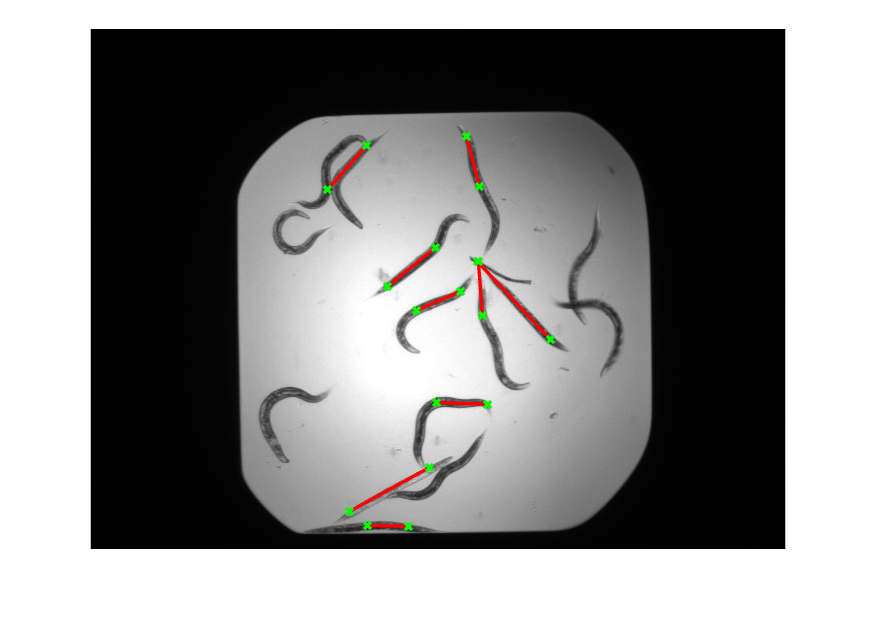

wormsBW = createBinaryWorms(worms);
wormSkel = bwmorph(wormsBW, "skel", Inf);
[H, T, R] = hough(wormSkel);
peaks = houghpeaks(H, 30, "NHoodSize", [55 11]);
hLines = houghlines(wormSkel, T, R, peaks);
plotHoughLines(worms, hLines)

## Task 1

In this practice, you will calculate the median lengths of the worm lines found using the Hough transform. Then, you'll be able to detect which images contain live worms and which contain dead worms by comparing the median lengths to a cutoff value.

To calculate the length of the detected lines, you need to extract the line's endpoints from the output of `houghlines`. This output is formatted as a structure array, where each detected line is an element of the array. You can extract an element of a structure array, `s`, using the standard syntax for indexing into an array: `s``(``1``)`.

oneLine = hLines(1)

oneLine = struct with fields:
    point1: [388 233]
    point2: [461 311]
     theta: -43
       rho: 125


## Task 2

Each line's endpoints are stored in two fields of the structure: `point1` and `point2`. You'll need these to compute the length. To extract a field (`a`) from a struct (`s`) use the dot notation: `s.a`.

pt1 = oneLine.point1

pt1 =    388   233


pt2 = oneLine.point2

pt2 =    461   311


## Task 3

To compute the distance between two points, you can compute the norm of their difference.

`norm``(``x2``-``x1``)`

diff = pt2 - pt1;
wormLength = norm(diff)

wormLength = 106.8316

## Task 4

To compute the lengths of the other detected lines, you can use the code that you wrote in the previous three tasks in the body of a for loop. The only changes required are selecting a new line at the start of each iteration of the loop and storing the resulting lengths in an array.

`for` `k` `=` `1``:``numWorms`

   `oneLine` `=` `hLines``(``k``)``;`

   `% compute the length `

   `... `

 `end`

numWorms = numel(hLines);
for k = 1:numWorms
    oneLine = hLines(k);
    pt1 = oneLine.point1;
    pt2 = oneLine.point2;
    diff = pt2 - pt1;
    wormLengths(k) = norm(diff);
end

## Task 5

The median length of the lines is a good descriptor of the state of the worms in the image. The median of a vector `v` is computed as `median(v)`.

medLength = median(wormLengths)

medLength = 60.3214

function plotHoughLines(image, hLines)
    % Show the image
    imshow(image)
    % Plot the hough transform lines
    hold on    
    numLines = length(hLines);
    for k = 1:numLines
        xy = [hLines(k).point1; hLines(k).point2];
        plot(xy(:, 1), xy(:, 2), "LineWidth", 2, "Color", "red",...
            "Marker", "x", "MarkerEdgeColor", "g")
    end
    hold off
end